%CW1
%Variables
clear; clc; close all;
format shortEng
syms R L i(t) t u0
di = diff(i, t);
equation = (u0 == R * i + L * di);

% Przypadek 1

% u0_vals = 0; %Napiecie w czasie t = 0
% i0_vals = [1, 3, 5]; %Natezenie w czasie t = 0
% R_value = 1;
% L_vals = 50e-3; % 50 mH

% Przypadek 2

u0_vals = [1, 3, 5];
i0_vals = 0;
R_value = 1;
L_vals = 50e-3; % 50 mH

% Przypadek 3
% 
% u0_vals = 5;
% i0_vals = 0;
% R_value = 1;
% L_vals = [10e-3,50e-3,100*10e-3]; % 10,50,100 mH

Rozwiązanie analityczne i(t) dla i(0) = 0 A, u0 = 1 V, R = 1, L = 5.000000e-02:


$$1-{\mathrm{e}}^{-20\,t}$$

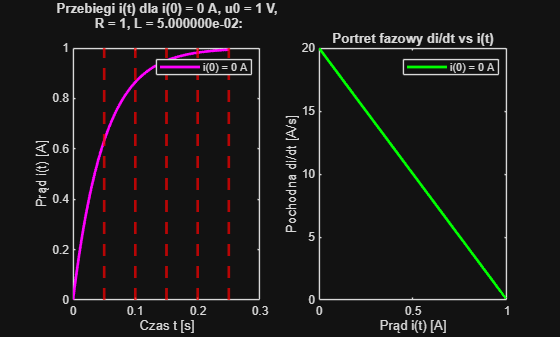

Rozwiązanie analityczne i(t) dla i(0) = 0 A, u0 = 3 V, R = 1, L = 5.000000e-02:


$$3-3\,{\mathrm{e}}^{-20\,t}$$

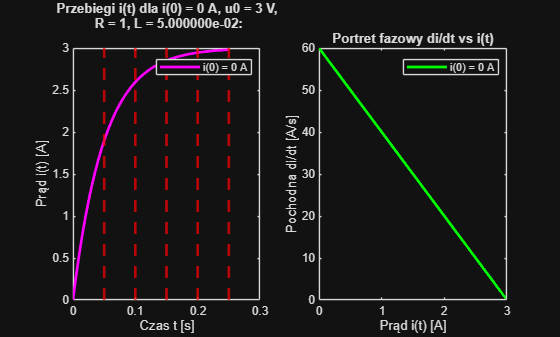

Rozwiązanie analityczne i(t) dla i(0) = 0 A, u0 = 5 V, R = 1, L = 5.000000e-02:


$$5-5\,{\mathrm{e}}^{-20\,t}$$

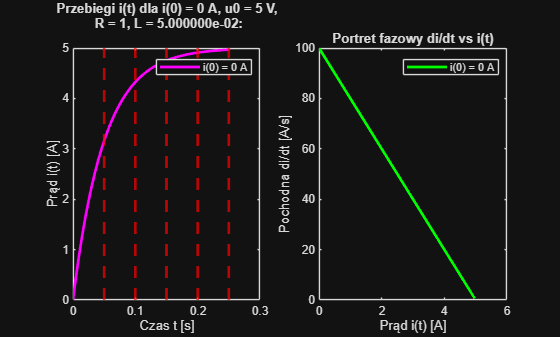

legenda = {};

for L_value = L_vals
    for u0_value = u0_vals
        for i0_value = i0_vals
            
            cond = (i(0) == i0_value);
            
            i_sol(t) = dsolve(subs(equation, [u0, R, L], [u0_value, R_value, L_value]), cond);
            
            fprintf('Rozwiązanie analityczne i(t) dla i(0) = %d A, u0 = %d V, R = %d, L = %d:\n', i0_value, u0_value, R_value, L_value);
            disp(i_sol(t));
            
            di_sol(t) = diff(i_sol, t);
            
            t_plot_vec = linspace(0, 5*L_value/R_value, 100);
                   
            i_plot_vals = subs(i_sol(t), t, t_plot_vec);
            di_plot_vals = subs(di_sol(t), t, t_plot_vec);
            
        
            %% Wykresy
            figure
            grid on;
            subplot(1, 2, 1);
            plot(t_plot_vec, i_plot_vals, LineWidth = 2, Color = "magenta");
            title(sprintf('Przebiegi i(t) dla i(0) = %d A, u0 = %d V,\n R = %d, L = %d:\n', i0_value, u0_value, R_value, L_value));
            xlabel('Czas t [s]'); ylabel('Prąd i(t) [A]');

            tau = L_value / R_value;
            for step=1:1:5
                xline(tau*step, 'r--', LineWidth = 2);
            end
            
            subplot(1, 2, 2);
            plot(i_plot_vals, di_plot_vals, LineWidth = 2,Color = "green");
            title(sprintf('Portret fazowy di/dt vs i(t)'));
            xlabel('Prąd i(t) [A]'); ylabel('Pochodna di/dt [A/s]');
            
            
            legenda = sprintf('i(0) = %d A', i0_value);
            subplot(1, 2, 1);
            legend(legenda);
            
            subplot(1, 2, 2);
            legend(legenda);
            
        end
    end
end